# Trouver la périodicité en utilisant l'autocorrélation

L'incertitude des mesures et le bruit rendent parfois difficile la détection d'un comportement oscillatoire dans un signal, même si ce comportement est attendu.

La séquence d'autocorrélation d'un signal périodique présente les mêmes caractéristiques cycliques que le signal lui-même. Ainsi, l'autocorrélation peut aider à vérifier la présence de cycles et à déterminer leurs durées.

Considérons un ensemble de données de température recueillies par un thermomètre à l'intérieur d'un immeuble de bureaux. L'appareil effectue un relevé toutes les demi-heures pendant quatre mois. Chargez les données et tracez-les. Soustrayez la moyenne pour vous concentrer sur les fluctuations de température. Convertissez la température en degrés Celsius. Mesurez le temps en jours. Le taux d'échantillonnage est donc de 2 mesures/heure × 24 heures/jour = 48 mesures/jour.

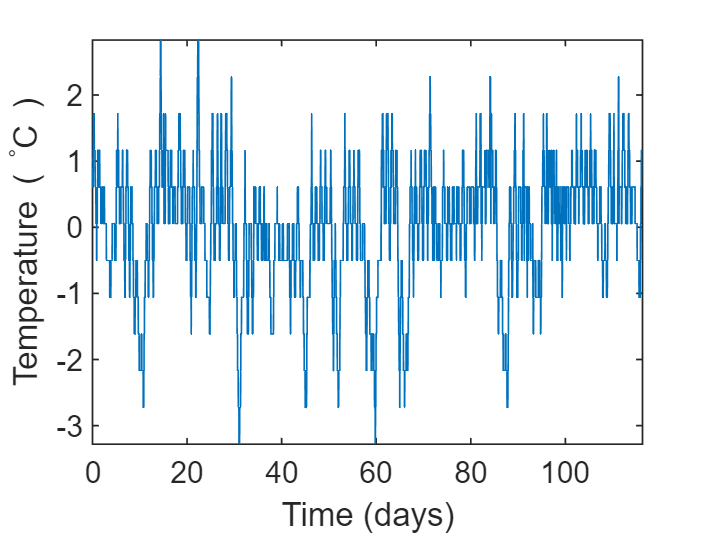

load officetemp

tempC = (temp-32)*5/9;

tempnorm = tempC-mean(tempC);

fs = 2*24;
t = (0:length(tempnorm) - 1)/fs;

plot(t,tempnorm)
xlabel('Time (days)')
ylabel('Temperature ( {}^\circC )')
axis tight

La température semble effectivement osciller, mais les longueurs des cycles ne sont pas facilement lisibles.

Calculez l'autocorrélation de la température de façon à ce qu'elle soit égale à l'unité au retard zéro. Limitez les décalages positifs et négatifs à trois semaines. Notez la double périodicité du signal.

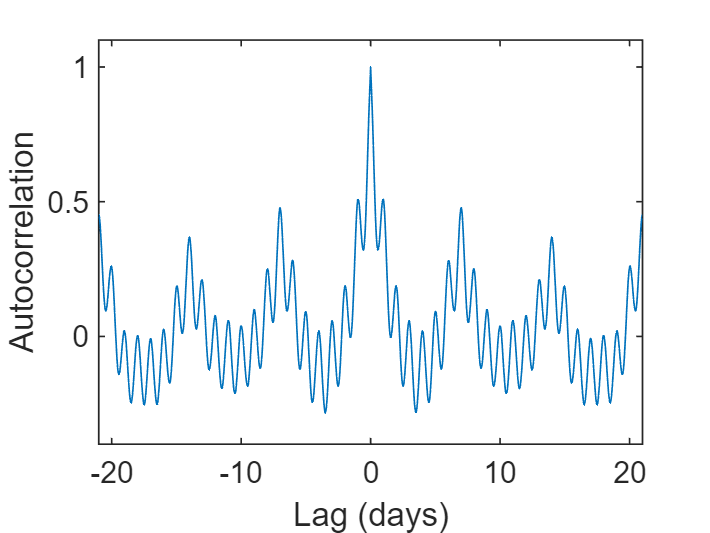

[autocor,lags] = xcorr(tempnorm,3*7*fs,'coeff');

plot(lags/fs,autocor)
xlabel('Lag (days)')
ylabel('Autocorrelation')
axis([-21 21 -0.4 1.1])

Déterminez les périodes courtes et longues en trouvant les emplacements des pics et en déterminant les différences de temps moyennes entre eux.

Pour trouver la longue période, limitez findpeaks pour rechercher les pics séparés par une distance supérieure à la courte période et dont la hauteur minimale est de 0,3.

[pksh,lcsh] = findpeaks(autocor);
short = mean(diff(lcsh))/fs

short = 1.0021



[pklg,lclg] = findpeaks(autocor, ...
    'MinPeakDistance',ceil(short)*fs,'MinPeakheight',0.3);
long = mean(diff(lclg))/fs

long = 6.9896

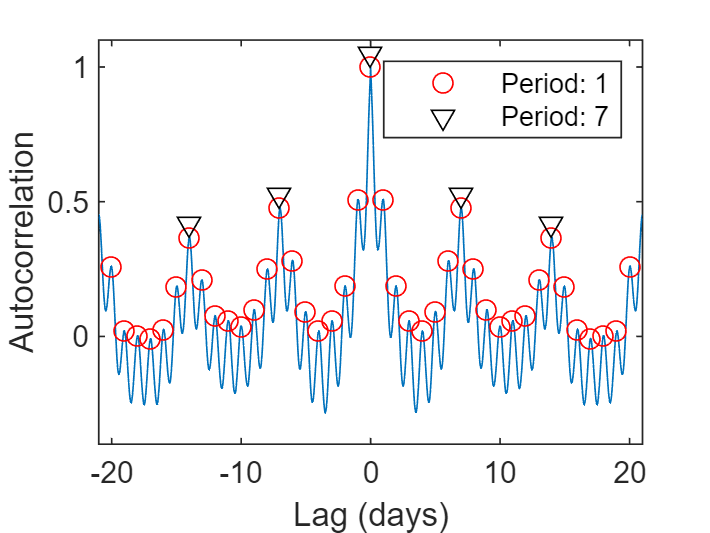


hold on
pks = plot(lags(lcsh)/fs,pksh,'or', ...
    lags(lclg)/fs,pklg+0.05,'vk');
hold off
legend(pks,[repmat('Period: ',[2 1]) num2str([short;long],0)])
axis([-21 21 -0.4 1.1])

Avec une très bonne approximation, l'autocorrélation oscille à la fois quotidiennement et hebdomadairement. Il faut s'y attendre, car la température dans le bâtiment est plus élevée lorsque les gens sont au travail et plus basse la nuit et le week-end.